## Facial Recognition

In this lecture, we will use the singular value decomposition to implement a facial recognition algorithm.  As a somewhat manageable example, the file `images.mat` contains the data for 80 black and white pictures of people's faces.  Each picture is $300\times 300$ pixels.  We will use these images to construct our facial recognition algorithm.  (We are using a `.mat` file instead of the usual `.csv` because MATLAB cannot handle extremely large `.csv` files.  The line `load('images.mat')` creates a matrix named `data` with the appropriate values.)  The photos in this data set come from the website [Labeled Faces in the Wild](http://vis-www.cs.umass.edu/lfw/), which aggregates photos to help people test machine learning algorithms.  I chose pictures of the man and woman with the most photos in the database, which happened to be George W. Bush and Serena Williams.  

**Waring: **This is a large data set (although it is barely large enough to make a working facial recognition method) and so this code will be pretty slow.  

load('images.mat');
h = 300;
w = 300;
[m, n] = size(data)

m = 80

n = 90000

In the last lecture, we saw that MATLAB can display images when they are stored in a matrix, but in this case each image is a row vector.  To put our images in the correct format, we need to use the `reshape` command to turn a row vector into a matrix.  The `reshape` function takes a vector/matrix and a vector containing the new dimensions.  For example, `reshape(data(1, :), [h, w])` turns the first row of the data matrix into a $300\times 300$ matrix.  

The following code displays several of the photographs.  (The `subplot` function just puts the pictures in a grid instead of one after another.)

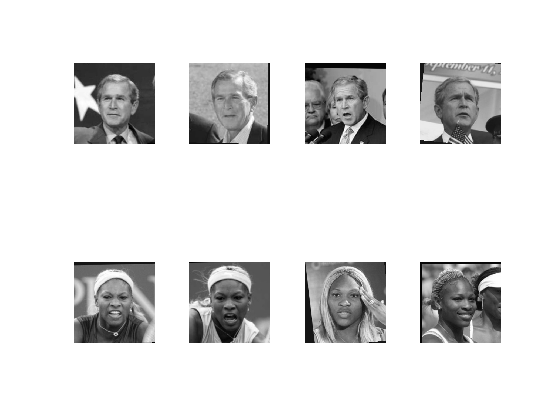

figure()
row_nums = [1, 10, 20, 30, 41, 50, 60, 70];
for k = 1:length(row_nums)
    img = reshape(data(row_nums(k), :), [h, w]);
    subplot(2, 4, k)
    imshow(img, [])
end

All of these pictures have many details in common.  For example, they all contain a face, so they have eyes, noses, mouths, etc.  We are interested in understanding the differences between each picture, rather than the features that separate faces from arbitrary images.  One way to summarize these common features is to find the average of all 80 faces.  We can do this with the `mean` function.  (By default, if you take the mean of a matrix, MATLAB finds the mean of each column, which is exactly what we want.)

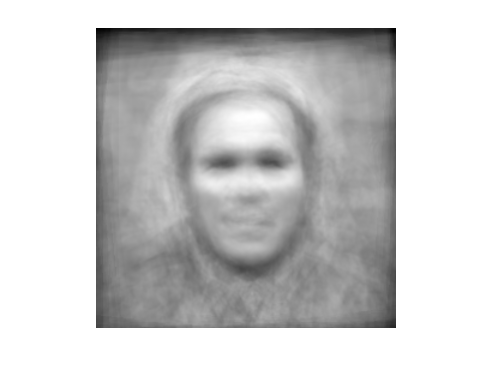

avg_img = mean(data);
figure()
imshow(reshape(avg_img, [h, w]), [])

We are interested in how the pictures deviate from this average.  To do this, we will make a new matrix where we subtract this average image from each row of `data`.  

X = data - ones(m, 1) * avg_img;

(Notice that we used the outer product of a vector of all ones with our average image.  This makes a matrix of the correct size where each row is a copy of `avg_img`.)  

We can now study our data set by finding the (reduced) SVD of X.  

[U, S, V] = svd(X, 'econ');

Notice the dimensions: U and S are $80\times 80$ and V is $900000\times 80$.  

We can first look at the singular values: 

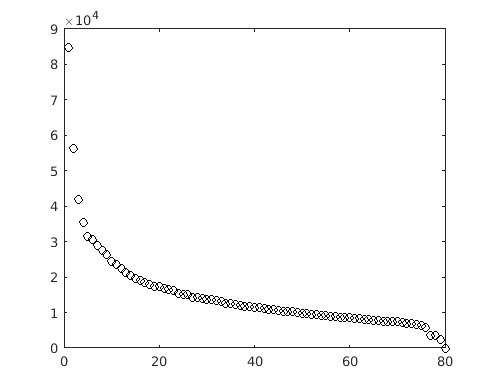

s = diag(S);
plot(s, 'ko')

These do not drop off nearly as dramatically as in some of our previous examples, but the first 20-40 singular values do seem more important than the latter ones.  We can quantify this with the (scaled) energies: 

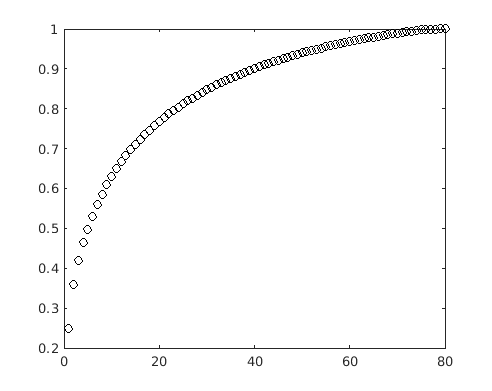

E = cumsum(s.^2) / sum(s.^2);
plot(E, 'ko')

It looks like the first 40 singular values account for roughly 90% of the information in our data set

E(40)

ans = 0.9013

but we would need 71 singular values to account for 99% of the energy.  

E(71)

ans = 0.9916

This means our data really is many-dimensional.  We can't reduce a set of faces to a small handful of variables.  (It's important to note that we have too small a data set to really do facial recognition.  To really make this work, we would want tens or hundreds of thousands of images.  If you try this out on a full data set - which you can get from LFW - then you will see that a few hundred or a few thousand singular values will account for a very large percentage of the energy.)

Now let's look at the principal directions of our data.  We saw in the last lecture that the columns of V corresponding to large singular values give you important information about patterns in your data.  In the context of facial recognition, these columns are usually called *eigenfaces* instead of principal directions.  In our case, we need most or all of the singular values to get a large percentage of the total energy, so most or all of the eigenfaces will be important.  Let's look at the first 9.  

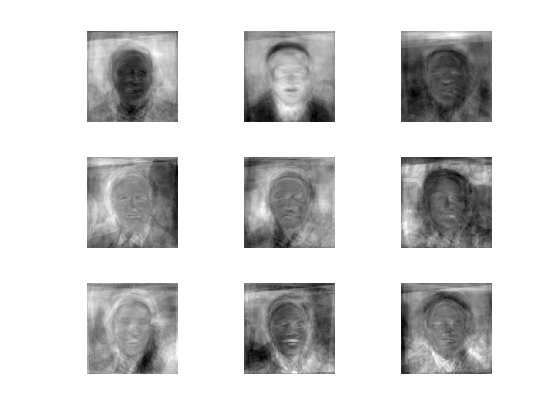

figure()
for k = 1:9
    img = reshape(V(:, k), [h, w]);
    subplot(3, 3, k)
    imshow(img, [])
end

Each of our images is different from the average face, and the difference can be written as a combination of these eigenfaces.  

How do you figure out what combination of these eigenfaces will give you one of the original images?  This information is contained in the matrices $U$ and $\Sigma$.  Typically, people combine those two matrices into one, which is called the score matrix: 

scores = U*S;

Each row of this matrix tells you how to combine the eigenfaces to retrieve a row of the matrix X.  For example, if the first row of `scores` were [2, -3, 1, -5], then you could recover the first image by multiplying the first eigenface by 2, the second eigenface by -3, the third by 1 and the fourth by -5 and then adding them together.  We can do this by multiplying the scores matrix by the transpose of V.  Notice that this is just the formula for SVD: 

$X = (U\Sigma)V^{T}$.

We can therefore reconstruct all of the original images by multiplying the scores by $V^{T}$.  Note that this actually only reconstructs X.  To get the original images, we then have to add back the average face.  Here are our reconstructions of the faces we showed at the beginning.  

figure()
reconstructed_X = scores * V';
row_nums = [1, 10, 20, 30, 41, 50, 60, 70];
for k = 1:length(row_nums)
    reconstructed_img = reconstructed_X(row_nums(k), :) + avg_img;
    subplot(2, 4, k)
    imshow(reshape(reconstructed_img, [h, w]), [])
end

These are identical to the originals because we used all 80 singular values and vectors.  

We could also try to compress these images by using a low rank approximation of X.  That is, we could keep the first N singular values and their corresponding vectors.  For example, here is the reconstruction using 71 singular values (which we saw retained about 99% of the information from the data set).  

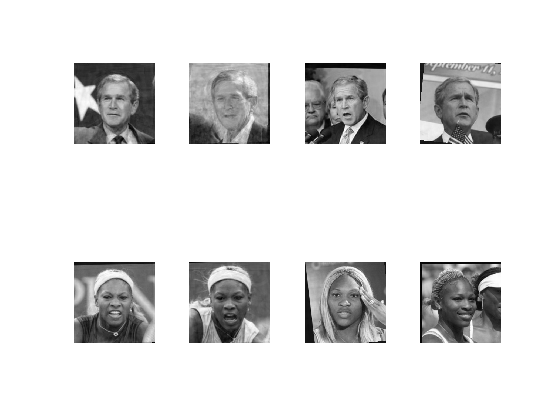

figure()
N = 71;
Uk = U(:, 1:N);
Sk = diag(s(1:N));
scores_k = Uk * Sk;
Vk = V(:, 1:N);
reconstructed_Xk = scores_k * Vk';
row_nums = [1, 10, 20, 30, 41, 50, 60, 70];
for k = 1:length(row_nums)
    reconstructed_img = reconstructed_Xk(row_nums(k), :) + avg_img;
    subplot(2, 4, k)
    imshow(reshape(reconstructed_img, [h, w]), [])
end

These look pretty good, although there are some visible imperfections, especially in the second image.  

Here is the reconstruction using 40 singular values (which we saw retained about 90% of the information from the data set).  

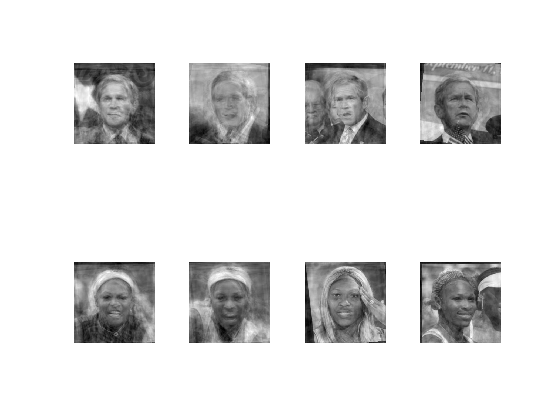

figure()
N = 40;
Uk = U(:, 1:N);
Sk = diag(s(1:N));
scores_k = Uk * Sk;
Vk = V(:, 1:N);
reconstructed_Xk = scores_k * Vk';
row_nums = [1, 10, 20, 30, 41, 50, 60, 70];
for k = 1:length(row_nums)
    reconstructed_img = reconstructed_Xk(row_nums(k), :) + avg_img;
    subplot(2, 4, k)
    imshow(reshape(reconstructed_img, [h, w]), [])
end

You can still tell who is in each picture, but these certainly don't qualify as "good" reconstructions.  

If we only use 9 singular values (which account for roughly 61% of the energy in the data set), then we get 

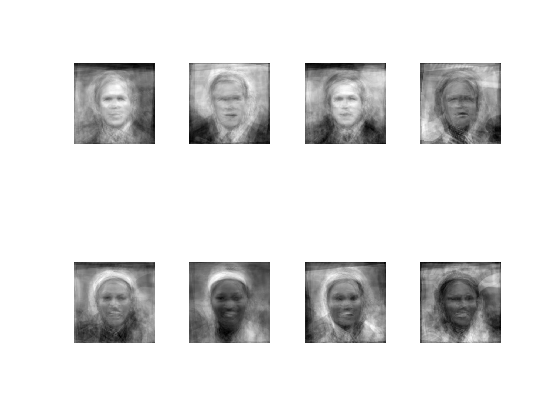

figure()
N = 9;
Uk = U(:, 1:N);
Sk = diag(s(1:N));
scores_k = Uk * Sk;
Vk = V(:, 1:N);
reconstructed_Xk = scores_k * Vk';
row_nums = [1, 10, 20, 30, 41, 50, 60, 70];
for k = 1:length(row_nums)
    reconstructed_img = reconstructed_Xk(row_nums(k), :) + avg_img;
    subplot(2, 4, k)
    imshow(reshape(reconstructed_img, [h, w]), [])
end

These images are averages of the 9 eigenfaces we displayed above.  

### Recognizing a New Face

Now we will use our data set to classify new images.  The file `testing_images.csv` contains a matrix with two rows.  Each row is an image of either George W. Bush or Serena Williams.  Our goal is to guess who is in each picture before we look at them.  

test_data = readmatrix('testing_images.csv');
img1 = test_data(1, :);
img2 = test_data(2, :);

The key idea is to notice that we could compute our scores in a different way.  Since $V$ is an orthogonal matrix, we can multiply both sides of our SVD formula by $V$ in order to cancel out the $V^{T}$ (because $V^TV = I$ is just the identity matrix).  We therefore get 

$XV = U\Sigma$.

This means that the scores can be calculated by multiplying the original matrix X by V.  In order to test our new data, we will pretend that our original data set only contained one of the new images.  That is, we will use img1 or img2 in place of X in this formula.  

score1 = (img1 - avg_img) * V;
score2 = (img2 - avg_img) * V;

Each of these is a $1\times 80$ score vector, just like one of the rows of the old scores matrix.  These new rows will not be the same as any of the old rows of scores, because they come from new images, but they will be closer to some than others.  To determine which person these images belong to, we will check which of the original images has scores closest to these.  To do so, we will calculate the distance between each row of `scores` and these two vectors, and then find the minimum of each of those distances.  (In the following code, we use the function `norm` to calculate distances.  `norm(x - y)` is the (Euclidean) distance between x and y.)

distances1 = zeros(1, 80);
distances2 = zeros(1, 80);
for k = 1:80
    distances1(k) = norm(score1 - scores(k, :));
    distances2(k) = norm(score2 - scores(k, :));
end
[~, index1] = min(distances1)

index1 = 31

[~, index2] = min(distances2)

index2 = 52

This tells us that the first test image is closest to image 31 and the second test image is closest to image 52.  Image 31 is a picture of George W. Bush, so we guess that the first test image is also of George W. Bush.  Image 52 is a picture of Serena Williams, so we guess that the second test image is also of Serena Williams.  

We can test this by checking both photos: 

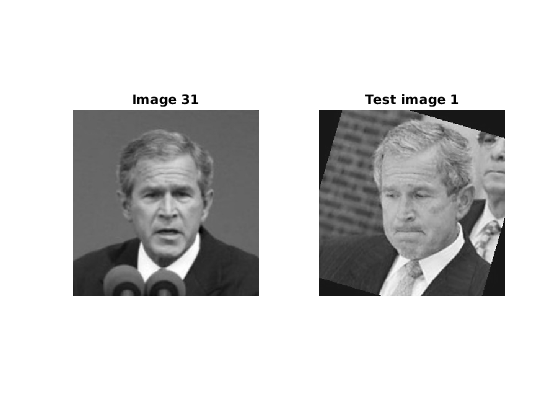

figure()
subplot(1, 2, 1)
img = X(index1, :) + avg_img;
imshow(reshape(img, [h, w]), [])
title("Image 31")

subplot(1, 2, 2)
imshow(reshape(img1, [h, w]), [])
title("Test image 1")

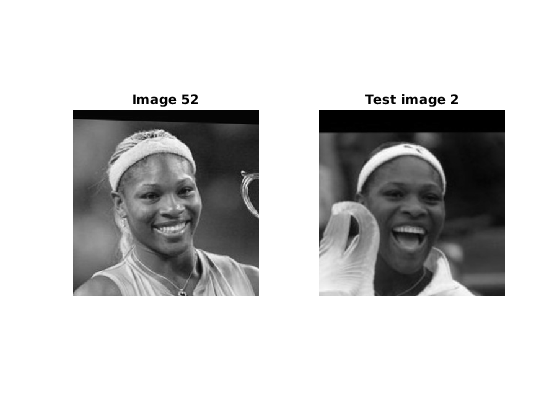

figure()
subplot(1, 2, 1)
img = X(index2, :) + avg_img;
imshow(reshape(img, [h, w]), [])
title("Image 52")

subplot(1, 2, 2)
imshow(reshape(img2, [h, w]), [])
title("Test image 2")

It's worth noting that we used the original scores to reconstruct our images from the eigenfaces.  As long as we used all 80 eigenfaces, we reconstructed the images perfectly.  What happens if we try to use our new scores to do the same thing?  These scores tell us how to get as close as possible to the new images by combining eigenfaces.  We won't get the exact images, because they weren't from the original data set, but mabye we can come close.  We can "reconstruct" these new images with the following code: 

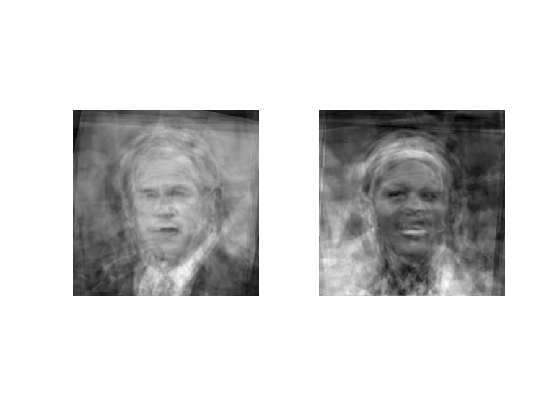

figure()
reconstructed_img1 = score1 * V' + avg_img;
subplot(1, 2, 1)
imshow(reshape(reconstructed_img1, [h, w]), [])

reconstructed_img2 = score2 * V' + avg_img;
subplot(1, 2, 2)
imshow(reshape(reconstructed_img2, [h, w]), [])

These are somewhat recognizable, but not particularly good reconstructions.  To some extent, this is just a consequence of our small data set.  If we had used 80,000 pictures instead of 80, this would have done a much better job.  (In fact, it probably would have done a much better job even if we only used the first 80 eigenfaces from a data set of 80,000 pictures.  More data is really important here!)  

It is worth mentioning some drawbacks of this approach.  Eigenface approaches were quite popular 20-30 years ago, but they are no longer used for serious facial recognition software.  There are two big problems.  First, the method requires *a lot* of data to be effective, and that data needs to be processed carefully.  (All the pictures need to be the same size, and they should be carefully scaled and rotated so that the faces are in the same spot and are the same size.  In addtion, it is best to have neutral backgrounds.  The test images should be in the same format.)  Second, even with enough data, the method is very sensitive to many features that we don't really care about.  In particular, different lighting or angles (i.e., if the faces are pointing past the camera instead of directly at it) matter more than which person is in the picture.  

SVD based methods are very powerful, and are the tool of choice in many different domains, but they have been displaced by other tools in the field of facial recognition.  With that said, eigenface methods are a great way to illustrate these methods because they automatically come with a great way to visualize results.  